clear all 
close all
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


The system is 

G = 4/(s*(s+2));

Spec 1: Kv = 20;

Spec 2: Phi_m > 50 deg

Spec 3: gm > 10dB

# Lead controller design

For a lead controller we have

C = Kc (T*s+1)/(alpha*T*s+1)

We need to design Kc, alpha, and T

### Spec 1: Kv = 20

We compute Kv as

Kv = lim_{s \to 0} s L(s) = 2 Kc

Then, we choose

Kc = 10;

The bode plot with this gain is given by

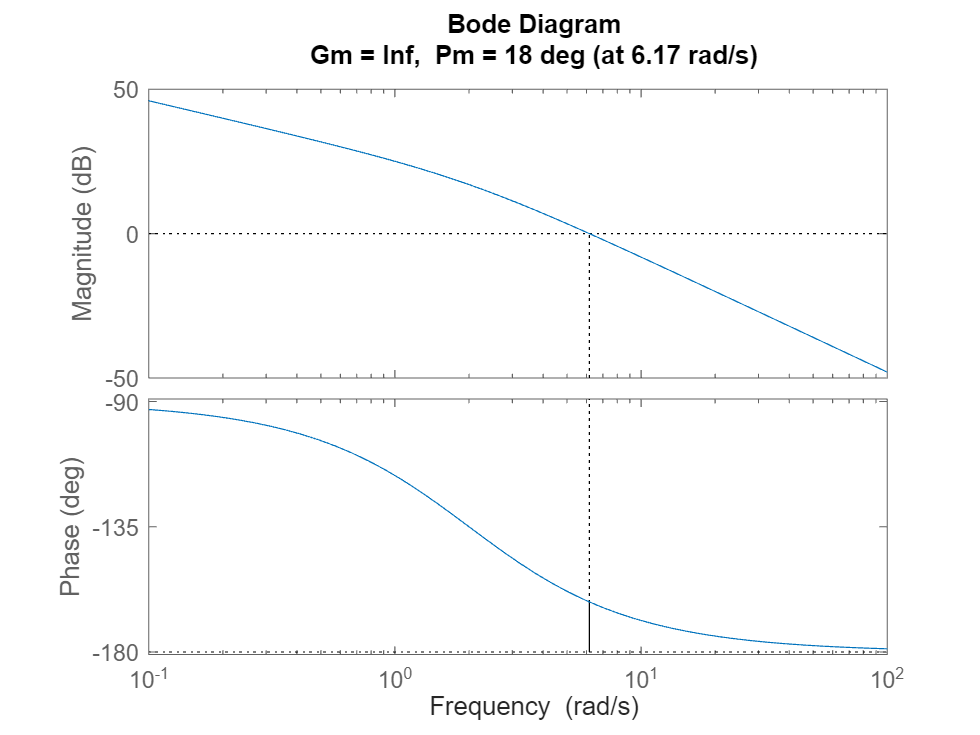

margin(Kc*G)

### Spec 2: phi_m > 50

At the gain crossover frequency we have a phase of 18. We need to bring this up to >50 (let's say 60)

This gives us the value for 

phi_cm = 60 - 18; 

which in turn can be used to compute alpha

alpha = (1-sin(phi_cm*pi/180))/(1+sin(phi_cm*pi/180));

Next, we select T to place the maximum phase boost at the desired frequency. The desired frequency (where we get the peak phase boost) is around the gain crossover frequency. Since the lead compensator will slightly increase this frequency, we set: 

omega_m = 9;

Then, T can be computed using

T = 1/(sqrt(alpha)*omega_m);

and the controller is finally given by

C = Kc * (T*s+1)/(alpha*T*s+1);

Let's verify the design by plotting the bode plot

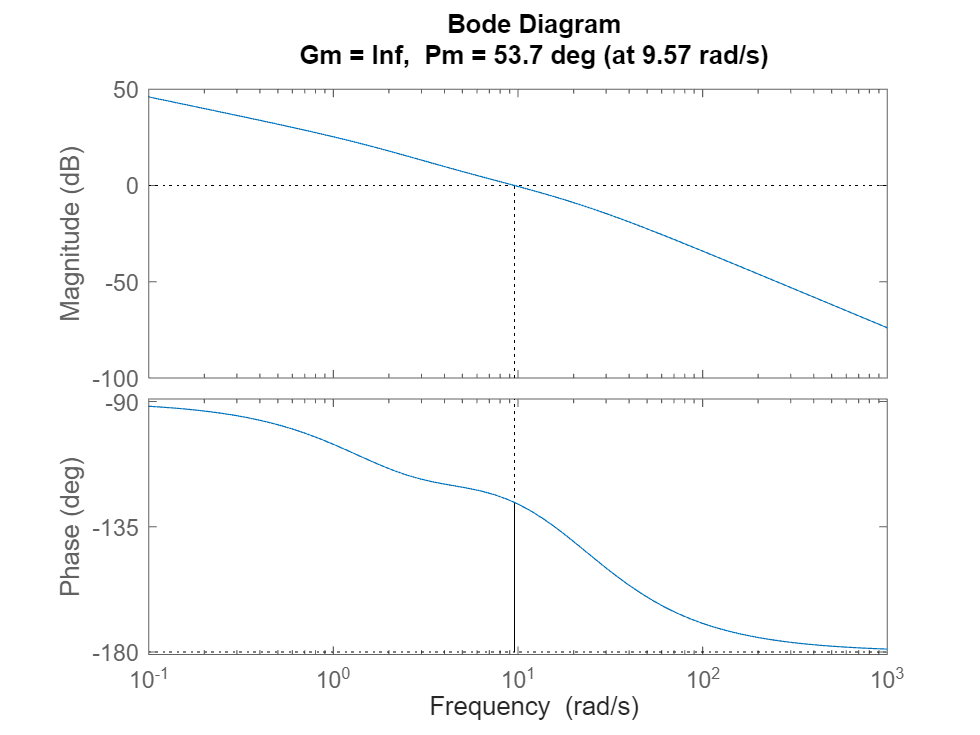

margin(C*G)

Notice that the above design also satisfies Spec 1.

# Lag compensator

For a lag controller we have

C = Kc (T*s+1)/(beta*T*s+1)

We need to design Kc, beta, and T

### Spec 1: Kv = 20

We compute Kv as

Kv = lim_{s \to 0} s L(s) = 2 Kc

Then, we choose

Kc = 10;

The bode plot with this gain is given by

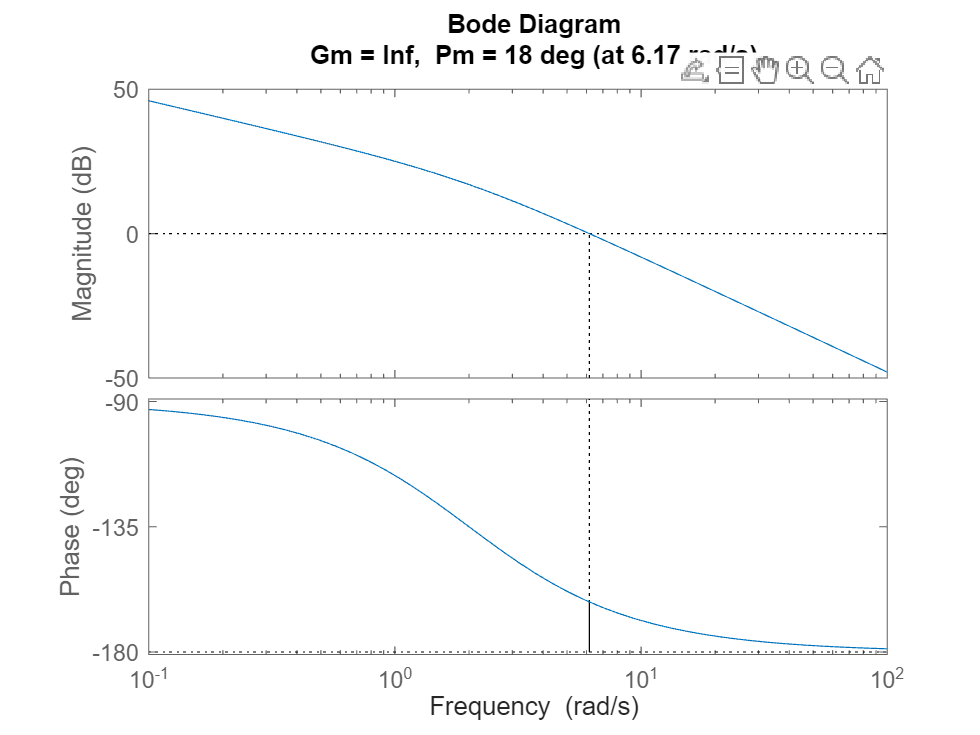

margin(Kc*G)

### Spec 2: phi_m > 50

The goal is to achieve a phase margin of at least 50 degrees (targeting around 60). The desired gain crossover frequency is near 1 rad/s, where the magnitude is roughly 24 dB. We want to reduce the gain by this amount to achieve the desired phase margin. To calculate beta, we use the relation:

20 log (beta) = 24 dB

which gives

beta = 10^(24/20);

Finally, to choose T, we place the zero of the lag compensator one decade below the new gain crossover frequency to ensure minimal impact on phase margin. Since the desired gain crossover frequency is around 1 rad/s, we set: 

T = 10/1;

This gives the lag compensator

C = Kc * (T*s+1)/(beta*T*s+1);

with bode plot

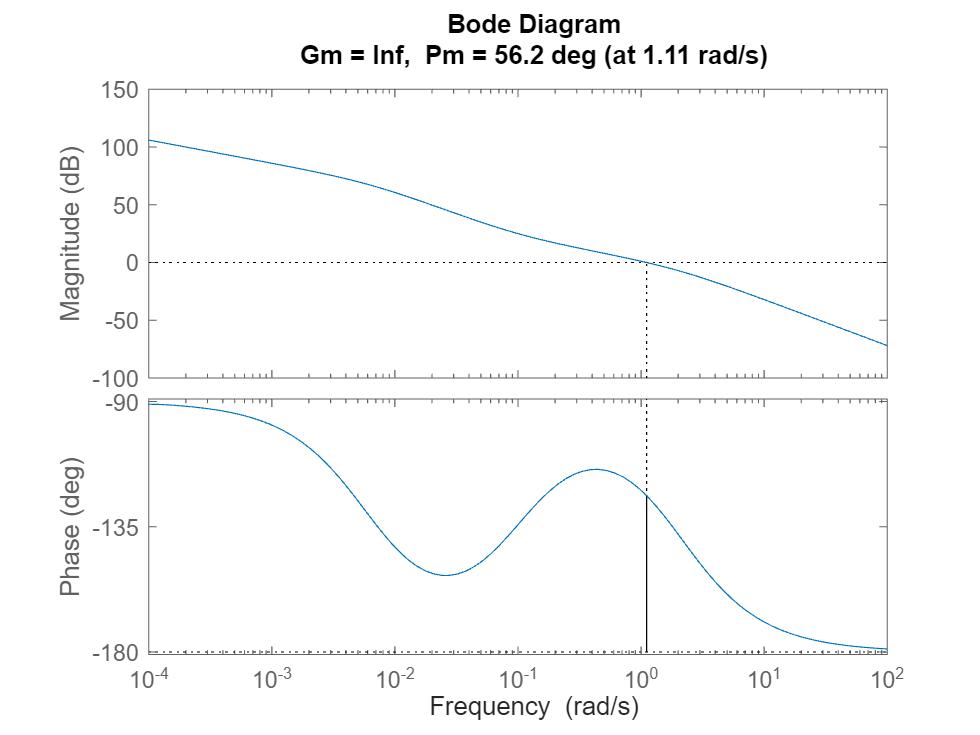

margin(C*G)

This design meets all specifications.